%LINEAR 
clc
 clear all
 close all
 x=input('enter x: ')

x =      1     2     3     4


 h=input('enter h: ')

h =      5     6     7     8


 N=length(x)

N = 4

 M=length(h)

M = 4

 l=M+N-1

l = 7

 y=zeros(1,l)

y =      0     0     0     0     0     0     0


 for n=1:l
     y(n)=0
     for k=max(1,n-M+1):min(n,N)
         y(n)=y(n)+x(n-k+1)*h(k)
     end
 end

y =      0     0     0     0     0     0     0


y =      5     0     0     0     0     0     0


y =      5     0     0     0     0     0     0


y =      5    10     0     0     0     0     0


y =      5    16     0     0     0     0     0


y =      5    16     0     0     0     0     0


y =      5    16    15     0     0     0     0


y =      5    16    27     0     0     0     0


y =      5    16    34     0     0     0     0


y =      5    16    34     0     0     0     0


y =      5    16    34    20     0     0     0


y =      5    16    34    38     0     0     0


y =      5    16    34    52     0     0     0


y =      5    16    34    60     0     0     0


y =      5    16    34    60     0     0     0


y =      5    16    34    60    24     0     0


y =      5    16    34    60    45     0     0


y =      5    16    34    60    61     0     0


y =      5    16    34    60    61     0     0


y =      5    16    34    60    61    28     0


y =      5    16    34    60    61    52     0


y =      5    16    34    60    61    52     0


y =      5    16    34    60    61    52    32


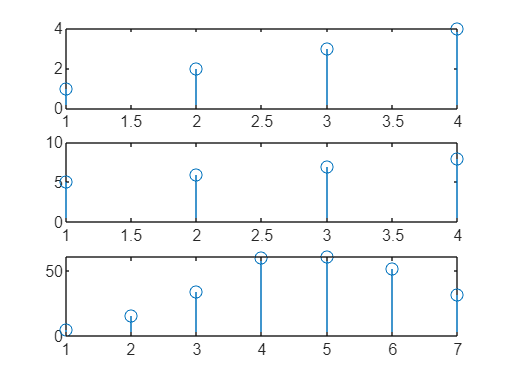

 subplot(3,1,1)
 stem(x)
 subplot(3,1,2)
 stem(h)
 subplot(3,1,3)
 stem(y)

%CIRCULAR
 clc
clear all
close all
x=input('enter x : ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=max(length(x),length(h))

N = 4

x=[x zeros(N-length(x))]

x =      1     2     3     4


h=[h zeros(N-length(h))]

h =      2     1     2     1


y=zeros(1,N)

y =      0     0     0     0


for n=1:N
    y(n)=0
    for k=1:N
        id=mod(n-k,N)+1
        y(n)=y(n)+h(k)*x(id)
    end
end

y =      0     0     0     0


id = 1

y =      2     0     0     0


id = 4

y =      6     0     0     0


id = 3

y =     12     0     0     0


id = 2

y =     14     0     0     0


y =     14     0     0     0


id = 2

y =     14     4     0     0


id = 1

y =     14     5     0     0


id = 4

y =     14    13     0     0


id = 3

y =     14    16     0     0


y =     14    16     0     0


id = 3

y =     14    16     6     0


id = 2

y =     14    16     8     0


id = 1

y =     14    16    10     0


id = 4

y =     14    16    14     0


y =     14    16    14     0


id = 4

y =     14    16    14     8


id = 3

y =     14    16    14    11


id = 2

y =     14    16    14    15


id = 1

y =     14    16    14    16


%DTMF
clc
clear all
close all
dtmf_fq=[
    941,1336;%0
    697,1209;%1
    697,1336;%2
    770,1209;%3
    770,1336;%4
    770,1477;%5
    852,1209;%6
    852,1336;%7
    852,1477;%8
    941,1336;%9
]

dtmf_fq =          941        1336
         697        1209
         697        1336
         770        1209
         770        1336
         770        1477
         852        1209
         852        1336
         852        1477
         941        1336


digit=input('enter digit : ')

digit = 4

if digit>=0 && digit<=9
    duration=0.5
    fs=14400
    t=0:1/fs:duration
    tone1=sin(2*pi*dtmf_fq(digit+1,1)*t)
    tone2=sin(2*pi*dtmf_fq(digit+1,2)*t)
    tone=tone1+tone2
    sound(tone)
else
    disp('invalid')
end

duration = 0.5000

fs = 14400

t =          0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0033    0.0034


tone1 =          0    0.3297    0.6225    0.8457    0.9744    0.9941    0.9026    0.7102    0.4384    0.1175   -0.2164   -0.5262   -0.7771   -0.9412   -1.0000   -0.9469   -0.7880   -0.5410   -0.2334    0.1002    0.4226    0.6978    0.8949    0.9920    0.9781    0.8549    0.6361    0.3461    0.0175   -0.3132   -0.6088   -0.8363   -0.9703   -0.9958   -0.9100   -0.7224   -0.4540   -0.1349    0.1994    0.5113    0.7660    0.9351    0.9997    0.9524    0.7986    0.5556    0.2504   -0.0828   -0.4067   -0.6852


tone2 =          0    0.5505    0.9191    0.9842    0.7242    0.2250   -0.3486   -0.8070   -0.9988   -0.8607   -0.4384    0.1288    0.6534    0.9622    0.9532    0.6293    0.0976   -0.4664   -0.8763   -0.9968   -0.7880   -0.3190    0.2554    0.7455    0.9893    0.9063    0.5240   -0.0314   -0.5764   -0.9311   -0.9781   -0.7022   -0.1942    0.3778    0.8251    0.9998    0.8443    0.4099   -0.1599   -0.6769   -0.9703   -0.9432   -0.6046   -0.0663    0.4939    0.8910    0.9938    0.7683    0.2890   -0.2857


tone =          0    0.8802    1.5416    1.8299    1.6985    1.2190    0.5540   -0.0968   -0.5604   -0.7432   -0.6548   -0.3974   -0.1237    0.0210   -0.0468   -0.3176   -0.6904   -1.0074   -1.1098   -0.8966   -0.3654    0.3788    1.1504    1.7375    1.9674    1.7612    1.1601    0.3147   -0.5590   -1.2442   -1.5869   -1.5384   -1.1645   -0.6180   -0.0848    0.2775    0.3903    0.2751    0.0395   -0.1656   -0.2043   -0.0081    0.3951    0.8861    1.2926    1.4466    1.2441    0.6855   -0.1177   -0.9709


%DFT
clc
clear all
close all
x=input('enter x : ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for k=0:N-1
    for n=0:N-1
        y(k+1)=y(k+1)+x(n+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     10
     1
     0
     0


y =   10.0000 + 0.0000i
   1.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -1.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   2.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


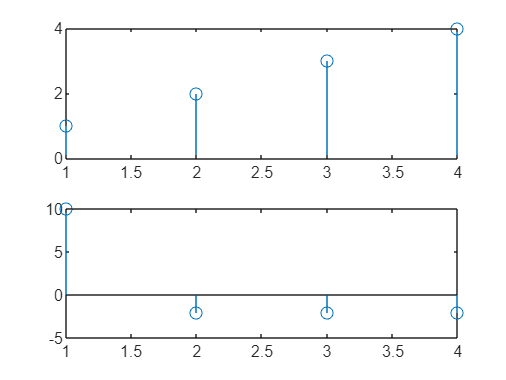

subplot(2,1,1)
stem(x)
subplot(2,1,2)
stem(y)

clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for k=0:N-1
    for n=0:N-1
        y(k+1)=y(k+1)+x(n+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     10
     1
     0
     0


y =   10.0000 + 0.0000i
   1.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -1.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   2.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


%IDFT
clc
clear all
close all
X=input('enter X')

X =      1     2     3     4


N=length(X)

N = 4

x=zeros(N,1)

x =      0
     0
     0
     0


for k=0:N-1
    for n=0:N-1
        x(k+1)=x(k+1)+X(n+1)*exp(1i*2*pi*n*k/N)
    end
    x(k+1)=x(k+1)/N
end

x =      1
     0
     0
     0


x =      3
     0
     0
     0


x =      6
     0
     0
     0


x =     10
     0
     0
     0


x =     2.5000
         0
         0
         0


x =     2.5000
    1.0000
         0
         0


x =    2.5000 + 0.0000i
   1.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   2.0000 - 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -2.0000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   0.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 + 0.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 - 2.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 - 2.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 + 2.0000i


x =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -0.5000 + 0.5000i


% linear, circular, dtmf, discrete fourier series
% inverse discrete fourier series,


%PDS
clc
clear all
close all
f1=500

f1 = 500

f2=2000

f2 = 2000

fs=8000

fs = 8000

N=200

N = 200

n=0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*n/fs)+2*sin(2*pi*f2*n/fs)

x =          0    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827


X=2*abs(fft(x,N))/N

X =     0.0503    0.0506    0.0516    0.0534    0.0561    0.0600    0.0655    0.0735    0.0856    0.1051    0.1408    0.2251    0.6490    0.6248    0.2009    0.1164    0.0804    0.0606    0.0481    0.0395    0.0333    0.0286    0.0250    0.0220    0.0196    0.0177    0.0160    0.0146    0.0134    0.0123    0.0114    0.0106    0.0099    0.0092    0.0087    0.0081    0.0077    0.0073    0.0069    0.0065    0.0062    0.0059    0.0057    0.0054    0.0052    0.0050    0.0048    0.0046    0.0044    0.0043


f=(0:N-1)*fs/N

f =            0          40          80         120         160         200         240         280         320         360         400         440         480         520         560         600         640         680         720         760         800         840         880         920         960        1000        1040        1080        1120        1160        1200        1240        1280        1320        1360        1400        1440        1480        1520        1560        1600        1640        1680        1720        1760        1800        1840        1880        1920        1960


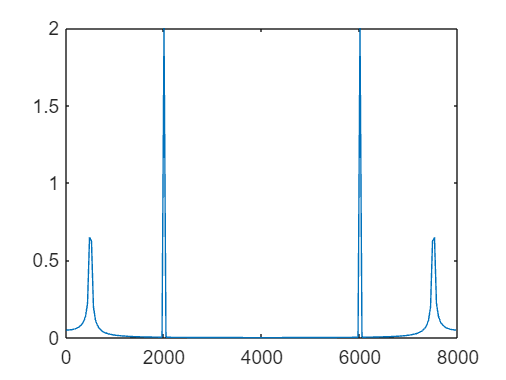

plot(f,X)

clc
clear all
close all
f1=500

f1 = 500

f2=2000

f2 = 2000

fs=8000

fs = 8000

N=200

N = 200

n=0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*n/fs)+2*sin(2*pi*f2*n/fs)

x =          0    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827


X=abs(fft(x,N))/N

X =     0.0251    0.0253    0.0258    0.0267    0.0280    0.0300    0.0328    0.0368    0.0428    0.0525    0.0704    0.1125    0.3245    0.3124    0.1004    0.0582    0.0402    0.0303    0.0241    0.0198    0.0167    0.0143    0.0125    0.0110    0.0098    0.0088    0.0080    0.0073    0.0067    0.0062    0.0057    0.0053    0.0049    0.0046    0.0043    0.0041    0.0038    0.0036    0.0034    0.0033    0.0031    0.0030    0.0028    0.0027    0.0026    0.0025    0.0024    0.0023    0.0022    0.0021


f=(0:N-1)*fs/N

f =            0          40          80         120         160         200         240         280         320         360         400         440         480         520         560         600         640         680         720         760         800         840         880         920         960        1000        1040        1080        1120        1160        1200        1240        1280        1320        1360        1400        1440        1480        1520        1560        1600        1640        1680        1720        1760        1800        1840        1880        1920        1960


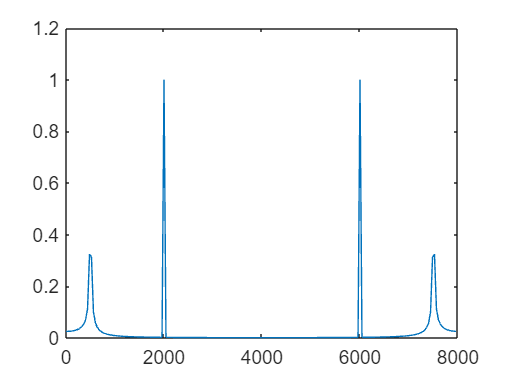

plot(f,X)

clc
clear all
close all
fs=1000

fs = 1000

frequency=50

frequency = 50

duration=1

duration = 0.5000

t=0:1/fs:duration

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=sin(2*pi*frequency*t)

sgnl =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


subplot(2,1,1)
plot(t,sgnl)
order=4

order = 4

fc=100

fc = 100

[b,a]=butter(order,fc/(fs/2),'low')

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


filsgnl=filter(b,a,sgnl)

filsgnl =          0    0.0015    0.0123    0.0500    0.1346    0.2755    0.4615    0.6622    0.8363    0.9439    0.9564    0.8628    0.6700    0.4002    0.0855   -0.2379   -0.5350   -0.7753   -0.9360   -1.0029   -0.9711   -0.8449   -0.6373   -0.3685   -0.0644    0.2457    0.5318    0.7662    0.9260    0.9954    0.9676    0.8450    0.6396    0.3715    0.0669   -0.2442   -0.5315   -0.7667   -0.9269   -0.9963   -0.9681   -0.8452   -0.6395   -0.3712   -0.0667    0.2444    0.5316    0.7667    0.9268    0.9962


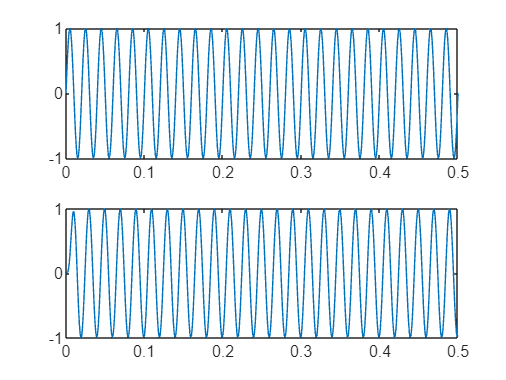

subplot(2,1,2)
plot(t,filsgnl)

clc
clear all
close all
f1=500

f1 = 500

f2=2000

f2 = 2000

fs=8000

fs = 8000

N=200

N = 200

n=0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*n/fs)+2*sin(2*pi*f2*n/fs)

x =          0    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827    0.7071   -1.0761    1.0000    2.9239    0.7071   -1.6173   -0.0000    1.6173   -0.7071   -2.9239   -1.0000    1.0761   -0.7071   -2.3827   -0.0000    2.3827


X=2*abs(fft(x,N))/N

X =     0.0503    0.0506    0.0516    0.0534    0.0561    0.0600    0.0655    0.0735    0.0856    0.1051    0.1408    0.2251    0.6490    0.6248    0.2009    0.1164    0.0804    0.0606    0.0481    0.0395    0.0333    0.0286    0.0250    0.0220    0.0196    0.0177    0.0160    0.0146    0.0134    0.0123    0.0114    0.0106    0.0099    0.0092    0.0087    0.0081    0.0077    0.0073    0.0069    0.0065    0.0062    0.0059    0.0057    0.0054    0.0052    0.0050    0.0048    0.0046    0.0044    0.0043


f=(0:N-1)/N

f =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


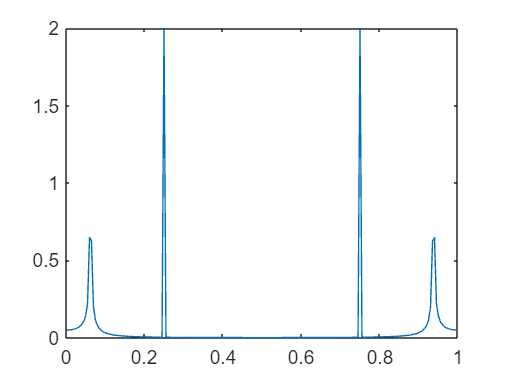

plot(f,X)

clc
clear all
close all
fs=1000

fs = 1000

duration=0.5

duration = 0.5000

frequency=50

frequency = 50

order=4

order = 4

fc=100

fc = 100

t=0:1/fs:duration

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sinsgnl=sin(2*pi*frequency*t)

sinsgnl =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


subplot(2,1,1)
plot(t,sinsgnl)
[b,a]=butter(order,fc/(fs/2),'low')

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


filsgnl=filter(b,a,sinsgnl)

filsgnl =          0    0.0015    0.0123    0.0500    0.1346    0.2755    0.4615    0.6622    0.8363    0.9439    0.9564    0.8628    0.6700    0.4002    0.0855   -0.2379   -0.5350   -0.7753   -0.9360   -1.0029   -0.9711   -0.8449   -0.6373   -0.3685   -0.0644    0.2457    0.5318    0.7662    0.9260    0.9954    0.9676    0.8450    0.6396    0.3715    0.0669   -0.2442   -0.5315   -0.7667   -0.9269   -0.9963   -0.9681   -0.8452   -0.6395   -0.3712   -0.0667    0.2444    0.5316    0.7667    0.9268    0.9962


subplot(2,1,2)
plot(t,filsgnl)

%linear 
%circular
%psd
%sinus sgnl
%dtmf
%dft
%idft










